# Robotics related tools

## Rigid Body 3D Representation

We have several tools to draw an object or a frame in 3D: 

- voxel

- psolido

- pframe

## Robot Manipulators Models

Tools to model and represent and robot arms, such as the ABB irb-120 in our laboratory:

- kin_irb120

- Virtual Reality model for ABB-irb120

- Simulink model for ABB-irb120

### voxel

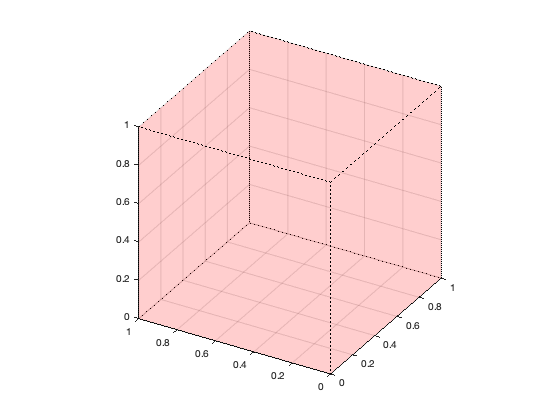

% VOXEL: Dibujamos un cubo de lado unidad, en color rojo, trasparente 0.1
a=1; b=1; c=1;
voxel([0 0 0],[a b c],'r',0.1);
grid on		% Se establece una rejilla
view(-60,30)	% Se establece el punto de vista
axis equal

### pframe

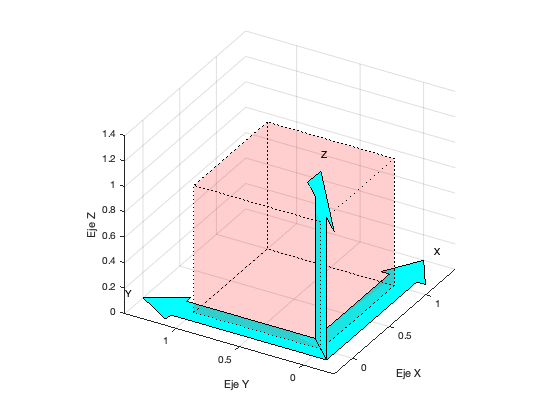

% PFRAME: dibujamos la trama T0 dada en coordenadas homogéneas
T0=eye(4);
pframe(T0,'c',1.4);
view(-60,30)

### psolido

% PSOLIDO: un prisma definido por sus 8 vértices. 
P=psolido

P =          0    1.0000    1.0000    0.5500    0.5500    0.4500         0         0    0.4500    0.5500    1.0000         0    0.4500    0.4500    0.5500    1.0000
         0         0         0    1.5000    1.5000    1.5000         0         0    1.5000    1.5000         0         0    1.5000    1.5000    1.5000         0
         0         0    0.5000    0.5000         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000         0         0         0


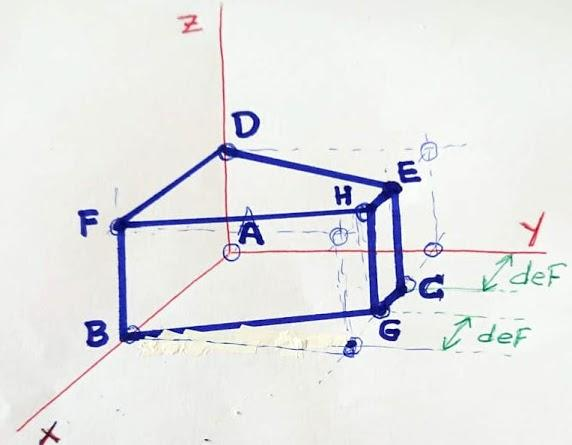

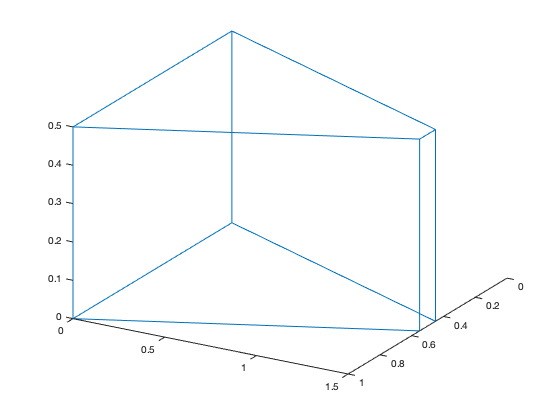

% La estructura de datos P es fácil de representar en 3D con plot3:
Pp=P'; plot3(Pp(:,1), Pp(:,2),Pp(:,3))
view([120 30])

### kin_irb120

% Calculamos una determinada configuración de los 5 primeros ejes:
T=kin_irb120(5);
syms t0 t1 t2 t3 t4
conf_home = round(subs(T,{t0, t1, t2, t3, t4},...
    {0 , 0, 0, 0 , 0 }))

$$conf\_home = \left(\begin{array}{cccc} 0 & 0 & 1 & 302\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 630\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Calculamos una determinada configuración de los 6 primeros ejes:
T=kin_irb120(6);
syms t0 t1 t2 t3 t4 t5
conf_home = round(subs(T,{t0, t1, t2, t3, t4, t5},...
    {0 , 0, 0, 0 , 0 , 0}))

$$conf\_home = \left(\begin{array}{cccc} 0 & 0 & 1 & 374\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 630\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Modelo del robot irb120, representado en VR

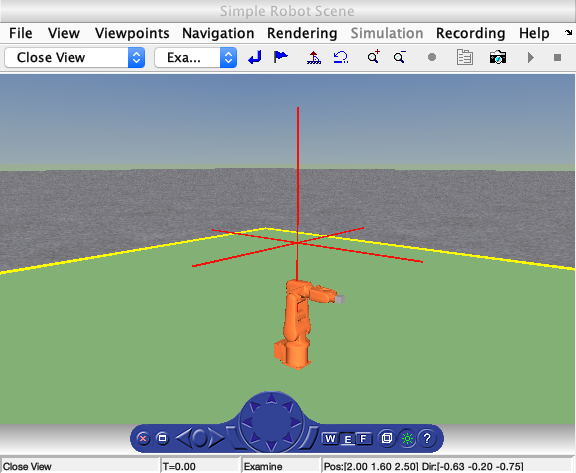

robotWorld = vrworld('robot_scene.wrl');
open(robotWorld);
rbt = importrobot('abb_irb_120d.urdf');
rbt.DataFormat = 'row';
n = vrinsertrobot(robotWorld,rbt);
vrdrawnow
view(robotWorld);

### Modelo del robot irb120, representado en Simulink

iiwaRBT = importrobot('abb_irb_120.urdf');
iiwaSM = smimport(iiwaRBT);

y ejecutar el modelo de simulink para visualizar el modelo y el robot.